

for i = 2:253
 DIA.Rocclose(i)=((DIA.close(i)-DIA.close(i-1))/DIA.close(i-1))*100;
end   


for i = 1:253
 DIA.Diffopenclose(i)=((DIA.open(i)-DIA.close(i))/DIA.open(i))*100;    
end


for i = 1:253
 DIA.DiffHighlow(i)=((DIA.high(i)-DIA.low(i))/DIA.low(i))*100;    
end


DIA.movavergopen=movaverg(DIA.open)

DIA = 253×10 table
       date       close       volume       open      high      low       Rocclose     Diffopenclose    DiffHighlow    movavergopen
    __________    ______    __________    ______    ______    ______    __________    _____________    ___________    ____________

    14/06/2017    213.84    5.4214e+06    213.78       214    212.98           NaN     -0.028066       0.47892             0      
    13/06/2017    213.37    2.4266e+06     212.8    213.39    212.75      -0.21979      -0.26786       0.30082             0      
    12/06/2017     212.4    3.6817e+06    212.46    212.78    211.88      -0.45461      0.028241       0.42477      


DIA.Diffopen=Diff(DIA.open,DIA.movavergopen);




DIA.movaverghigh=movaverg(DIA.high);
DIA.Diffhigh=Diff(DIA.open,DIA.movaverghigh);


DIA.movaverglow=movaverg(DIA.low);;

DIA.Difflow=Diff(DIA.open,DIA.movaverglow);
DIA.movavergclose=movaverg(DIA.close);

DIA.Diffclose=Diff(DIA.open,DIA.movavergclose);
DIA.movavergvolume=movaverg(DIA.volume);

DIA.Diffvolume=Diff(DIA.volume,DIA.movavergvolume);

%S&P preprocessing 
SP.movaverghigh=movaverg(SP.High);
SP.Diffhigh=Diff(SP.High,SP.movaverghigh);
DIA.sp=scale11(SP.Diffhigh);
%Dax preprocessimg

DIA.daxopen=scale11(dax.Open);
%nasdaq preprocessing
nasdaq.movavergopen=movaverg(nasdaq.Open);
nasdaq.Diffopen=Diff(nasdaq.Open,nasdaq.movavergopen);

DIA.nasdaq=scale11(nasdaq.Diffopen);
%preprocessing dow jon indu
dowjonesindu.movaverglow=movaverg(dowjonesindu.Low);

dowjonesindu.Difflow=Diff(dowjonesindu.Low,dowjonesindu.movaverglow);

DIA.dowjonesindu=scale11(dowjonesindu.Difflow);
%preprocessing dowjonestrans
dowjonestrans.movavergclose=movaverg(dowjonestrans.Close);
dowjonestrans.Diffclose=Diff(dowjonestrans.Close,dowjonestrans.movavergclose);
DIA.dowjonestrans=scale11(dowjonestrans.Diffclose);

%final scaling

DIA.open=scale11(DIA.open);
DIA.Diffopenclose=scale11(DIA.Diffopenclose);
DIA.DiffHighlow=scale11 (DIA.DiffHighlow);
DIA.Diffopen(11:253)=scale11(DIA.Diffopen(11:253));
DIA.Diffhigh(11:253)=scale11(DIA.Diffhigh(11:253));
DIA.Difflow(11:253)= scale11(DIA.Difflow(11:253));
DIA.Diffvolume(11:253)=scale11(DIA.Diffvolume(11:253));
DIA.Diffclose(11:253)=scale11(DIA.Diffclose(11:253));
DIA.Diffhigh(11:253)=scale11(DIA.Diffhigh(11:253));
DIA.close=scale11(DIA.close);



% 
% t=1:253;
% plot(t,DIA.Rocclose);
% plot(t,DIA.Diffopenclose);

%creation de la population  et determination du vecteur de forcating
N=151;
pop=init(5);
% popcro=init(2); forr=forcast(N,popcro,DIA);er=error1(forr,N,popcro,DIA);

forcasted=forcast(N,pop,DIA)

forcasted =     0.1173    0.2332    0.9819    0.2593    0.9293
    0.1183    0.1481    0.9978    0.2515    0.8228
    0.1138    0.1295    0.9983    0.2520    0.8228
    0.0989    0.1148    0.9987    0.2527    0.8484
    0.0895    0.1995    0.9637    0.2774    0.9304
    0.0903    0.1979    0.9837    0.2735    0.9307
    0.1100    0.1803    0.9938    0.2562    0.8611
    0.0782    0.1814    0.9987    0.2720    0.9505
    0.0890    0.1452    0.9392    0.3846    0.9190
    0.0816    0.2278    0.9927    0.2736    0.9429


err=error1(forcasted,N,pop,DIA)

err =    59.1526
   54.6053
   14.4268
   34.1600
    8.9520


pop=order(pop);
pop(:).erreur

ans = 8.9520

ans = 14.4268

ans = 34.1600

ans = 54.6053

ans = 59.1526


while pop(1).erreur>0.005
   pop=mutation(3,45,DIA,pop);
   pop=crossover1(pop,3,DIA,N);
   pop=petmuta    tion(1,pop,N,DIA);
   disp('dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk')
   pop(:).erreur
   
end

succedsssssssssssssssssssssssssssssssssssssssssssssssssssssss


les valeurs compare
    7.1332

   54.6053

les valeurs compare
   10.0793

   54.6053

les valeurs compare
   14.2790

   54.6053



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.2278

ans = 8.9520

ans = 14.4268

ans = 34.1600

ans = 54.6053

les valeurs compare
    7.0179

   54.6053

les valeurs compare
    8.2644

   54.6053

les valeurs compare
   14.2790

   54.6053



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.2278

ans = 8.9520

ans = 14.4268

ans = 34.1600

ans = 54.6053

succedsssssssssssssssssssssssssssssssssssssssssssssssssssssss


les valeurs compare
   10.4685

   34.1600

les valeurs compare
    4.2887

   34.1600

les valeurs compare
   10.4685

   34.1600



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

ans = 34.1600

les valeurs compare
    6.5784

   34.1600

les valeurs compare
    6.5784

   34.1600

les valeurs compare
    6.5784

   34.1600



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

ans = 34.1600

les valeurs compare
    4.2887

   34.1600

les valeurs compare
   11.1818

   34.1600

les valeurs compare
   10.4685

   34.1600



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

ans = 34.1600

les valeurs compare
    6.5784

   34.1600

les valeurs compare
   10.4685

   34.1600

les valeurs compare
    4.2887

   34.1600



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

ans = 34.1600

les valeurs compare
    9.9843

   34.1600

les valeurs compare
   10.4685

   34.1600

les valeurs compare
   10.4685

   34.1600



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

ans = 34.1600

succedsssssssssssssssssssssssssssssssssssssssssssssssssssssss


les valeurs compare
    9.9553

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   14.6102

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   14.6102

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   14.6102

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   14.6102

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   14.6102

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   14.6102

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   14.6102

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
   14.6102

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9448

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   14.6102

   14.4268

les valeurs compare
    9.9553

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9448

   14.4268

les valeurs compare
   11.2406

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

les valeurs compare
    6.0671

   14.4268

les valeurs compare
    9.9553

   14.4268

les valeurs compare
    6.0671

   14.4268



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0657

ans = 0.2001

ans = 0.2278

ans = 8.9520

ans = 14.4268

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

les valeurs compare
    0.0613

    0.0613

crossover effectue
les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

ans = 0.0613

les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613

les valeurs compare
    0.0613

    0.0613



ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686

crossover effectue
les valeurs compare
    0.0686

    0.0686



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

les valeurs compare
    0.0686

    0.0686

les valeurs compare
    0.0686

    0.0686



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

les valeurs compare
    0.0686

    0.0686

les valeurs compare
    0.0686

    0.0686



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

ans = 0.0686

les valeurs compare
    0.0686

    0.0686

les valeurs compare
    0.0686

    0.0686

les valeurs compare
    0.0686

    0.0686



s=11:N

s =     11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45


pop(:).erreur

ans = 0.0576

ans = 0.0576

ans = 0.0576

ans = 0.0576

ans = 0.0576

ans = 0.0576

ans = 0.0576

ans = 0.0576

ans = 0.0605

ans = 0.0617

forcasted=forcast(N,pop,DIA)

forcasted =     0.8428    0.8428    0.8428    0.8428    0.8428    0.8428    0.8428    0.8428    0.8808    0.8777
    0.8724    0.8724    0.8724    0.8724    0.8724    0.8724    0.8724    0.8724    0.8994    0.8765
    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8771    0.8986    0.8765
    0.8827    0.8827    0.8827    0.8827    0.8827    0.8827    0.8827    0.8827    0.8884    0.8765
    0.8444    0.8444    0.8444    0.8444    0.8444    0.8444    0.8444    0.8444    0.8616    0.8766
    0.8408    0.8408    0.8408    0.8408    0.8408    0.8408    0.8408    0.8408    0.8654    0.8770
    0.8648    0.8648    0.8648    0.8648    0.8648    0.8648    0.8648    0.8648    0.8876    0.8765
    0.9030    0.9030    0.9030    0.9030    0.9030    0.9030    0.9030    0.9030    0.8773    0.8689
    0.9215    0.9215    0.9215    0.9215    0.9215    0.9215    0.9215    0.9215    0.8579    0.8752
    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.8809    0.880

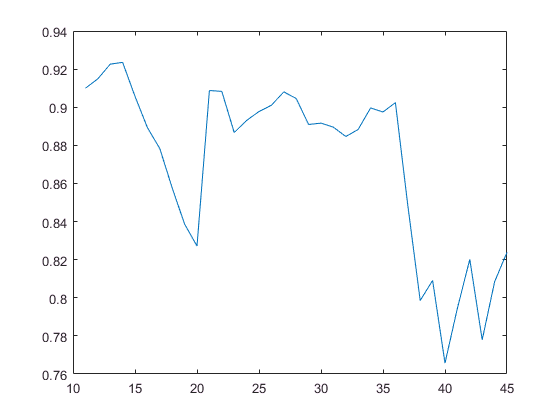

plot(s,DIA.close(11:N))

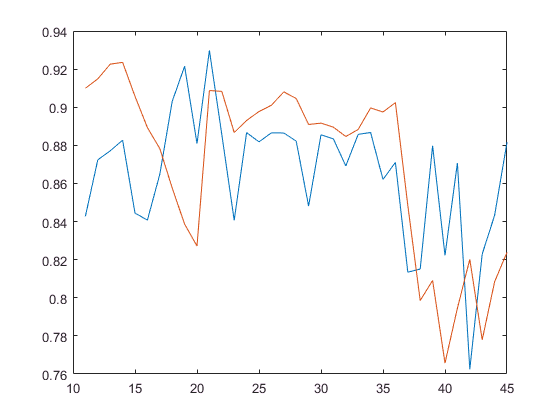

plot(s,forcasted(:,1),s,DIA.close(11:N))

% plot(s,forcasted(:,4),s,DIA.close(11:N))
pop(1).affiche()

niveau2
  Columns 1 through 12

   -0.1514   -2.9653    2.3576    4.9204    0.9181    3.1572   -1.7872    4.1474    1.2313   -3.0097    1.1473   -1.2543

  Columns 13 through 24

    3.4223   -1.0857    1.2644    0.2062   -3.2487    2.3351   -0.2914    0.1993   -0.2371   -3.5409    3.5712    4.3344

  Columns 25 through 36

   -2.5873    2.2934   -0.5273   -2.1293    0.4328   -3.7581    2.3907   -2.0427    0.5971    1.0949    3.1365    3.1237

niveau3
    2.2112   -0.1511   -2.3295    1.3933    0.7335    0.5096



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


ans =   network with properties:

           c: 15
     niveau0: [1×1 layer]
     niveau1: [1×1 layer]
     niveau2: [1×1 layer]
    niveau21: [1×1 layer]
     niveau3: [1×1 layer]
        rank: []
      erreur: 0.0580
      output: 0.8797


pop(2).affiche()

niveau2
  Columns 1 through 12

   -0.1514   -2.9653    2.3576    4.9204    0.9181    3.1572   -1.7872    4.1474    1.2313   -3.0097    1.1473   -1.2543

  Columns 13 through 24

    3.4223   -1.0857    1.2644    0.2062   -3.2487    2.3351   -0.2914    0.1993   -0.2371   -3.5409    3.5712    4.3344

  Columns 25 through 36

   -2.5873    2.2934   -0.5273   -2.1293    0.4328   -3.7581    2.3907   -2.0427    0.5971    1.0949    3.1365    3.1237

niveau3
    2.2112   -0.1511   -2.3295    1.3933    0.7335    0.5096



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


ans =   network with properties:

           c: 15
     niveau0: [1×1 layer]
     niveau1: [1×1 layer]
     niveau2: [1×1 layer]
    niveau21: [1×1 layer]
     niveau3: [1×1 layer]
        rank: []
      erreur: 0.0580
      output: 0.8797


% z=init(1);zz=init(1);z3=init(1);
% z3(1).egalite(z(1));
% forcasted1=forcast(14,z,DIA)

forcasted1 =     0.0920
    0.1198
    0.1029
    0.0884


% err=error1(forcasted1,14,z,DIA)

err = 2.6631

% forcasted12=forcast(14,zz,DIA)

forcasted12 =     0.0064
    0.0088
    0.0091
    0.0098


% err2=error1(forcasted12,14,zz,DIA)

err2 = 3.2994

% ddd=1:4

ddd =      1     2     3     4


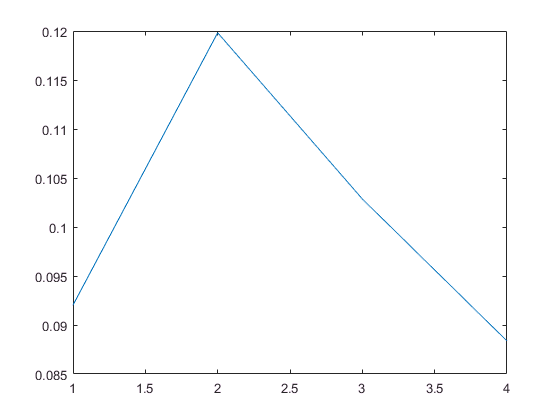

% plot(ddd,forcasted1(:,1))

% z(1).affiche()

niveau2
  Columns 1 through 12

    3.2483    3.7962   -2.0665   -4.1997    1.1282    1.4595    2.8715    2.4067    2.8642   -0.1708    0.5500    4.7228

  Columns 13 through 24

    3.0840   -2.0641   -3.5961   -1.5389   -3.6362    2.9956   -2.9008    4.5963    2.8495    4.1077   -3.0611   -1.9575

  Columns 25 through 36

    0.3066    4.5582    2.4157    4.7546    2.2354    1.6916    0.5378    4.5513   -1.9544    3.2886   -0.8724    0.8470

niveau3
   -3.1006   -2.0287    3.6696    2.9961   -4.5880    4.5342



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


ans =   network with properties:

           c: 15
     niveau0: [1×1 layer]
     niveau1: [1×1 layer]
     niveau2: [1×1 layer]
    niveau21: [1×1 layer]
     niveau3: [1×1 layer]
        rank: []
      erreur: 2.6631
      output: 0.0884


% zz(1).affiche()

niveau2
  Columns 1 through 12

   -4.9249   -2.4500   -1.0356    2.2883    1.9240    3.7754   -1.5435    4.3883    2.2500    2.9528    1.7242    4.1124

  Columns 13 through 24

   -4.1598   -2.1037   -3.1582    4.0575    1.8212   -3.3735    3.1683    2.0560   -2.1838    4.1474   -3.4688   -0.4162

  Columns 25 through 36

   -0.6128    4.0035   -2.7949    3.0932   -3.0486    4.8017    4.1697    1.7416   -4.6939   -4.3379   -3.7477   -2.3595

niveau3
   -4.1861    0.4207    3.3038   -3.1021    1.0865    0.8192



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


ans =   network with properties:

           c: 15
     niveau0: [1×1 layer]
     niveau1: [1×1 layer]
     niveau2: [1×1 layer]
    niveau21: [1×1 layer]
     niveau3: [1×1 layer]
        rank: []
      erreur: 3.2994
      output: 0.0098


% z(1).crossover(zz(1))

ans =   network with properties:

           c: 15
     niveau0: [1×1 layer]
     niveau1: [1×1 layer]
     niveau2: [1×1 layer]
    niveau21: [1×1 layer]
     niveau3: [1×1 layer]
        rank: []
      erreur: 2.6631
      output: 0.0884


%  z(1).affiche()

niveau2
  Columns 1 through 12

   -0.8383    0.6731   -1.5510   -0.9557    1.5261    2.6174    0.6640    3.3975    2.5571    1.3910    1.1371    4.4176

  Columns 13 through 24

   -0.5379   -2.0839   -3.3771    1.2593   -0.9075   -0.1890    0.1338    3.3262    0.3328    4.1276   -3.2650   -1.1868

  Columns 25 through 36

   -0.1531    4.2808   -0.1896    3.9239   -0.4066    3.2466    2.3538    3.1464   -3.3242   -0.5246   -2.3100   -0.7562

niveau3
   -3.6433   -0.8040    3.4867   -0.0530   -1.7507    2.6767



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


ans =   network with properties:

           c: 15
     niveau0: [1×1 layer]
     niveau1: [1×1 layer]
     niveau2: [1×1 layer]
    niveau21: [1×1 layer]
     niveau3: [1×1 layer]
        rank: []
      erreur: 2.6631
      output: 0.0272


% z3(1).affiche()

niveau2
  Columns 1 through 12

    3.2483    3.7962   -2.0665   -4.1997    1.1282    1.4595    2.8715    2.4067    2.8642   -0.1708    0.5500    4.7228

  Columns 13 through 24

    3.0840   -2.0641   -3.5961   -1.5389   -3.6362    2.9956   -2.9008    4.5963    2.8495    4.1077   -3.0611   -1.9575

  Columns 25 through 36

    0.3066    4.5582    2.4157    4.7546    2.2354    1.6916    0.5378    4.5513   -1.9544    3.2886   -0.8724    0.8470

niveau3
   -3.1006   -2.0287    3.6696    2.9961   -4.5880    4.5342



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


ans =   network with properties:

           c: 15
     niveau0: [1×1 layer]
     niveau1: [1×1 layer]
     niveau2: [1×1 layer]
    niveau21: [1×1 layer]
     niveau3: [1×1 layer]
        rank: []
      erreur: 0
      output: 0.5000


% zz(1).affiche()

niveau2
  Columns 1 through 12

   -4.9249   -2.4500   -1.0356    2.2883    1.9240    3.7754   -1.5435    4.3883    2.2500    2.9528    1.7242    4.1124

  Columns 13 through 24

   -4.1598   -2.1037   -3.1582    4.0575    1.8212   -3.3735    3.1683    2.0560   -2.1838    4.1474   -3.4688   -0.4162

  Columns 25 through 36

   -0.6128    4.0035   -2.7949    3.0932   -3.0486    4.8017    4.1697    1.7416   -4.6939   -4.3379   -3.7477   -2.3595

niveau3
   -4.1861    0.4207    3.3038   -3.1021    1.0865    0.8192



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


ans =   network with properties:

           c: 15
     niveau0: [1×1 layer]
     niveau1: [1×1 layer]
     niveau2: [1×1 layer]
    niveau21: [1×1 layer]
     niveau3: [1×1 layer]
        rank: []
      erreur: 3.2994
      output: 0.0098


% forcasted1=forcast(14,z,DIA)

forcasted1 =     0.9982
    0.9982
    0.9981
    0.9982


% err=error1(forcasted1,14,z,DIA)

err = 0.0268

% ddd=1:4

ddd =      1     2     3     4


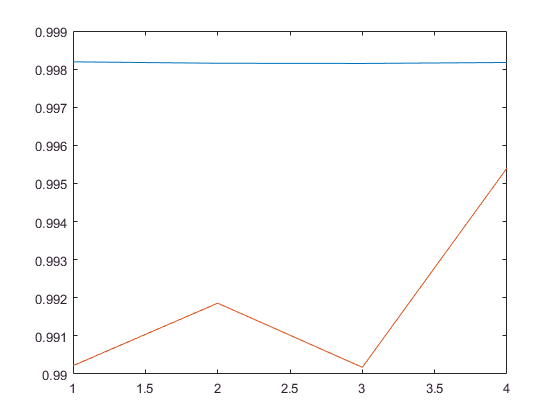

% plot(ddd,forcasted1(:,1),ddd,forcasted12(:,1))

%  pop(1).erreur
% forcasted=forcast(N,pop,DIA)

s=11:N

s =     11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45


pop=order(pop)

pop =   1×10 network array with properties:

    c
    niveau0
    niveau1
    niveau2
    niveau21
    niveau3
    rank
    erreur
    output


pop(:).erreur

ans = 0.0580

ans = 0.0580

ans = 0.0580

ans = 0.0580

ans = 0.0580

ans = 0.0580

ans = 0.0580

ans = 0.0580

ans = 0.0580

ans = 0.0580

err=error1(forcasted,N,pop,DIA)

err =     0.0580
    0.0580
    0.0580
    0.0580
    0.0580
    0.0580
    0.0580
    0.0580
    0.0580
    0.0580


plot(s,DIA.close(11:N))

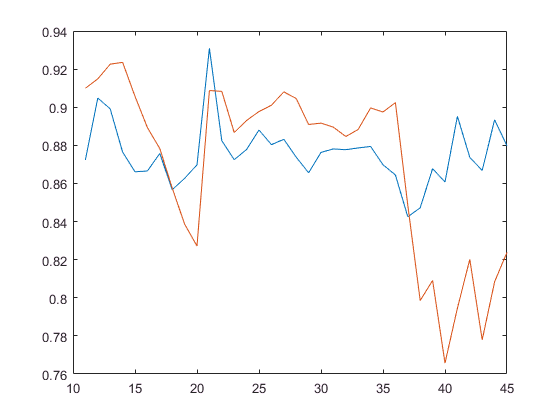

plot(s,forcasted(:,1),s,DIA.close(11:N))

plot(s,forcasted(:,7),s,DIA.close(11:N))

plot(s,forcasted(:,5),s,DIA.close(11:N))

oo=init(2)
oo(1).affiche();


